# Spectral Graph Clustering Algorithm

Name : Rigved Patki

Email : [patki@kth.se](mailto:patki@kth.se) 

Group : Assignment Group 8

## Clearing previous variables and command window

clc; clear ; close all;

## Reading dataset from ./data and visualising the dataset

File path to the dataset expample1.dat or expample2.dat

dataset_path = fullfile('.','data','example2.dat');

Reading the csv data from the file path

dataset = csvread(dataset_path);


 Getting the source nodes and destination node

source_nodes = dataset(:,1);
destination_nodes = dataset(:,2);

Adding edges to graph

G = graph(source_nodes,destination_nodes);

Displaying the Graph

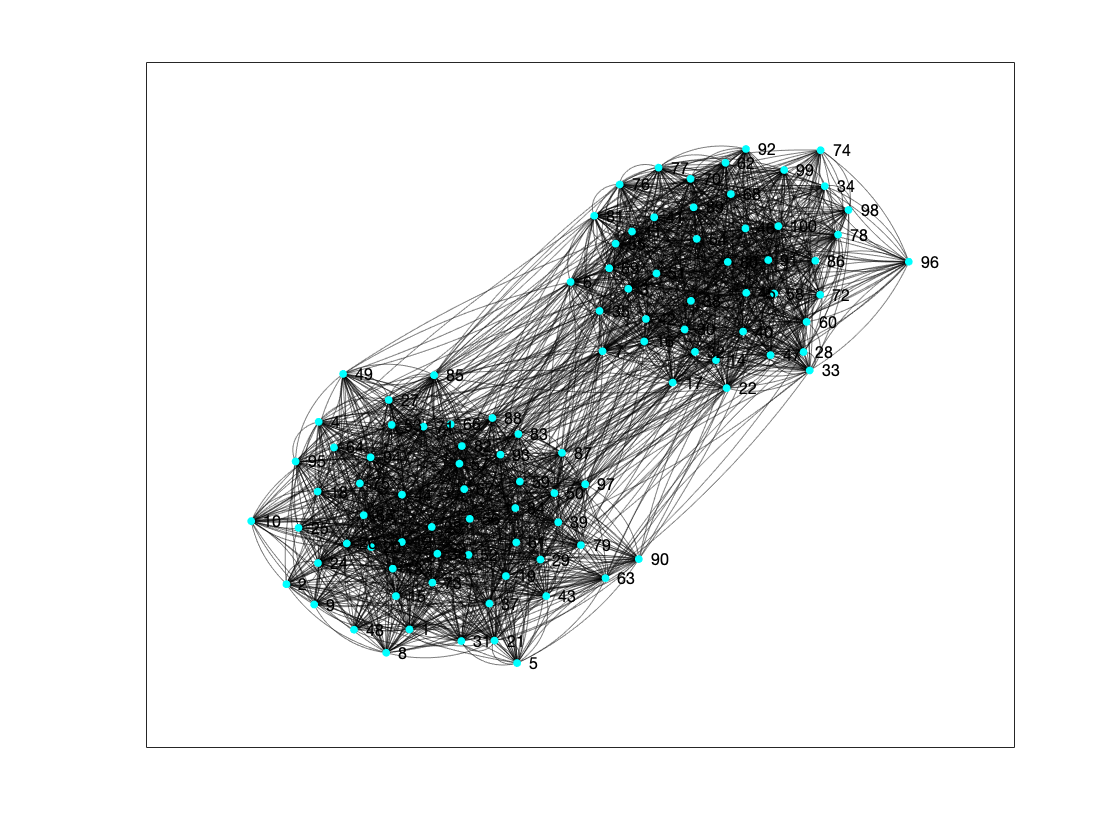

figure('Name','Original graph without clusters');
p = plot(G);
p.LineWidth= 0.2500;
p.LineStyle= '-';
p.Marker = '.';
p.NodeColor = 'c';
p.EdgeColor = 'k';
p.MarkerSize = 10;

## Algorithm

Construct the adjacency matrix (affinity matrix)

max_ids = max(max(source_nodes, destination_nodes));
As = sparse(source_nodes, destination_nodes, 1, max_ids, max_ids);
A = full(As);


 Construct diagonal matrix

Di = diag(sum(A,2));

Construct normalized laplacian matrix ( L = D^(-1/2)AD(-1/2) )

L = (Di^(-0.5)) * A * (Di^(-0.5));

 Calculating k largest eigenvectors of L and stack them into X

% [X,D1] = eigs(L, k); 
[X, D1] = eigs(L, size(L,1)-1); 
% size(L) - 1 to use eigs() instead of eig()

Construct eigenvalues for D1

eigenvalues = diag(D1);
eig_gaps = -1*diff(eigenvalues); 
% -1* used because eigenvalues is sorted 
% in desc. order so diffs are negatives.

Plot Eignevalues of sorted normalized of Laplacian matrix 

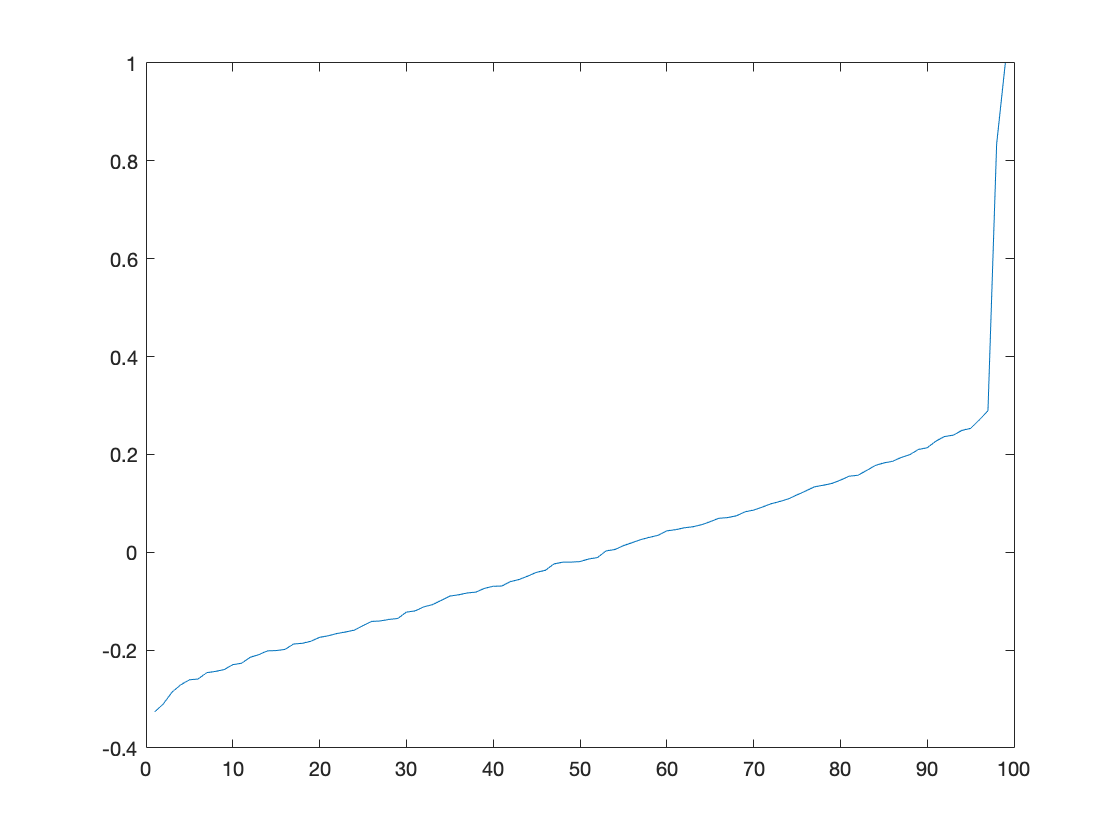

figure('Name', 'Eignevalues of sorted normalized of Laplacian matrix ');
plot(sort(eigenvalues)); % plotting the eignevalues (ascending order) and normalized (unit “length”) eigenvectors of L

Calculating optimal value of k

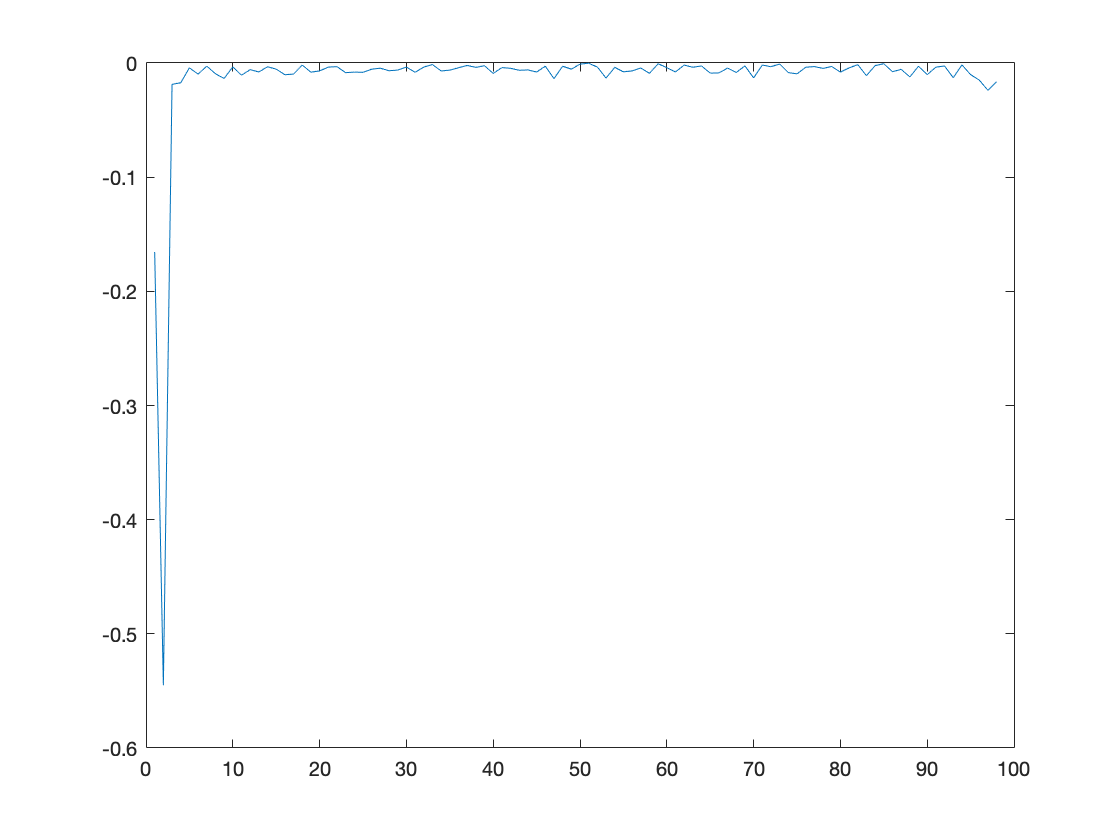

array_k = diff(flipud(sort(eigenvalues)));
figure('Name', 'Plotting for k ');
plot(array_k);

[w,k]=min(array_k)

w = -0.5451

k = 2

Constructing Matrix X by stacking eigen values

X = X(:,(1:k));

Create Y by renormalizing each of X's rows to have unit length

Y = X./(sum(X.^2,2)).^(0.5);


Apply K-means to rows of Y

Idx = kmeans(Y, k);

Display graphs with clusters

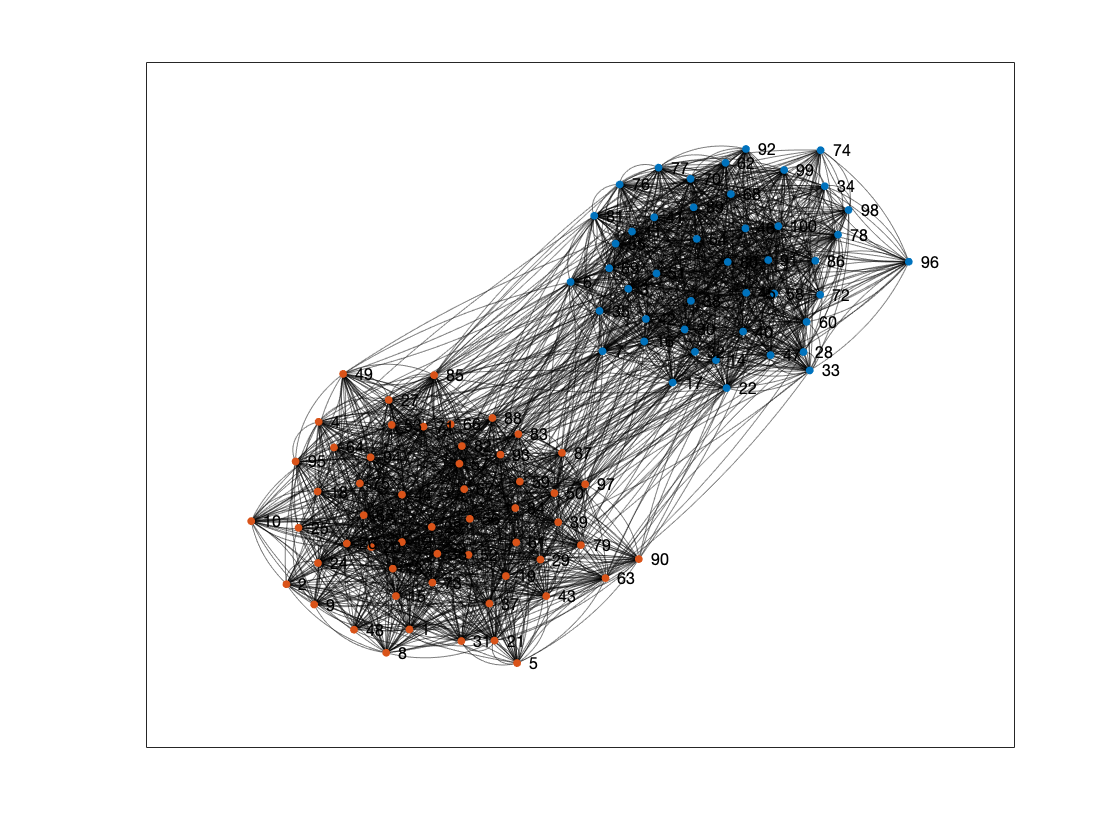

figure('Name','Graph with clusters');
p = plot(G);
p.EdgeColor = 'k';
p.LineWidth= 0.2500;
p.LineStyle= '-';
p.Marker = '.';
p.MarkerSize = 10;
cmap = lines();

for i=1:size(Idx,1)
    cluster = Idx(i,1);
    highlight(p,i,'NodeColor',cmap(cluster,:));
end

## **Find communities using the Fiedler Vector**

Display sparsity pattern

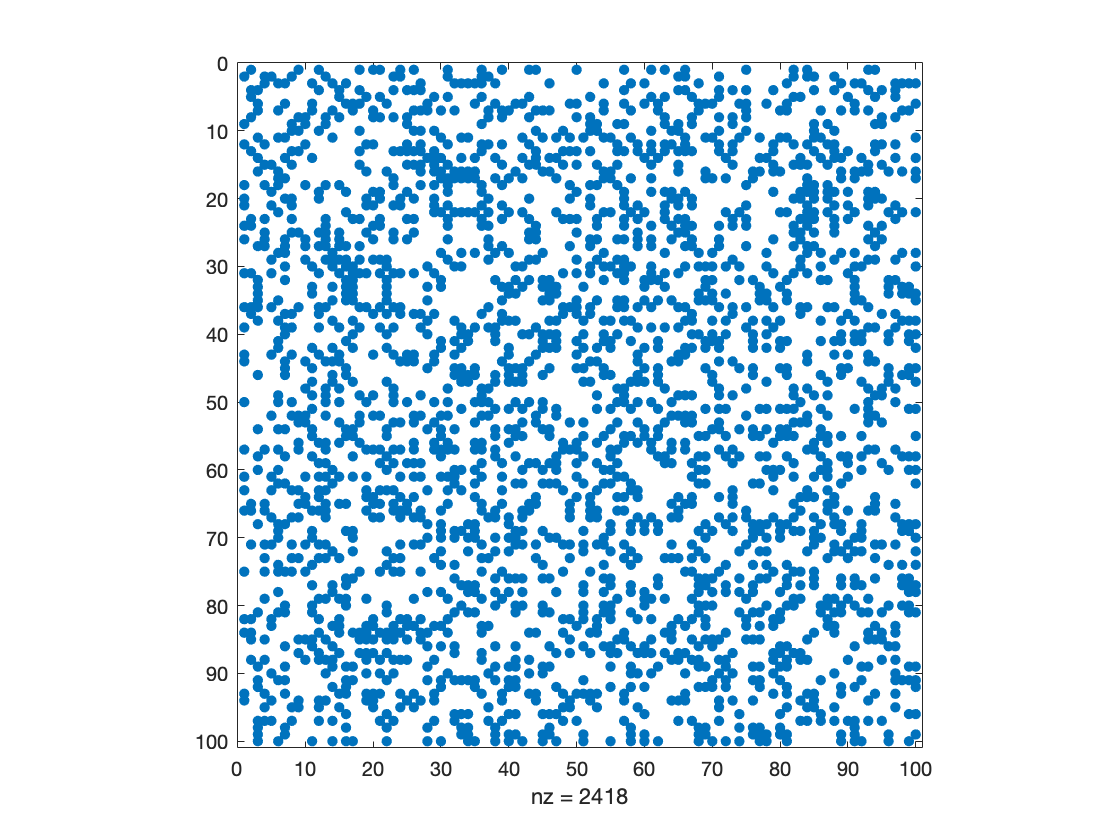

figure('Name', 'Sparsity Pattern');
spy(A);

Construct laplacian matrix

H = simplify(G);
new_L = laplacian(H);

Get eigenvalues from laplacian matrix

[v,new_D] = eigs(new_L,k,'smallestreal');

Construct Fiedler Vector

fv = v(:,2);

Plot the sorted Fiedler vector

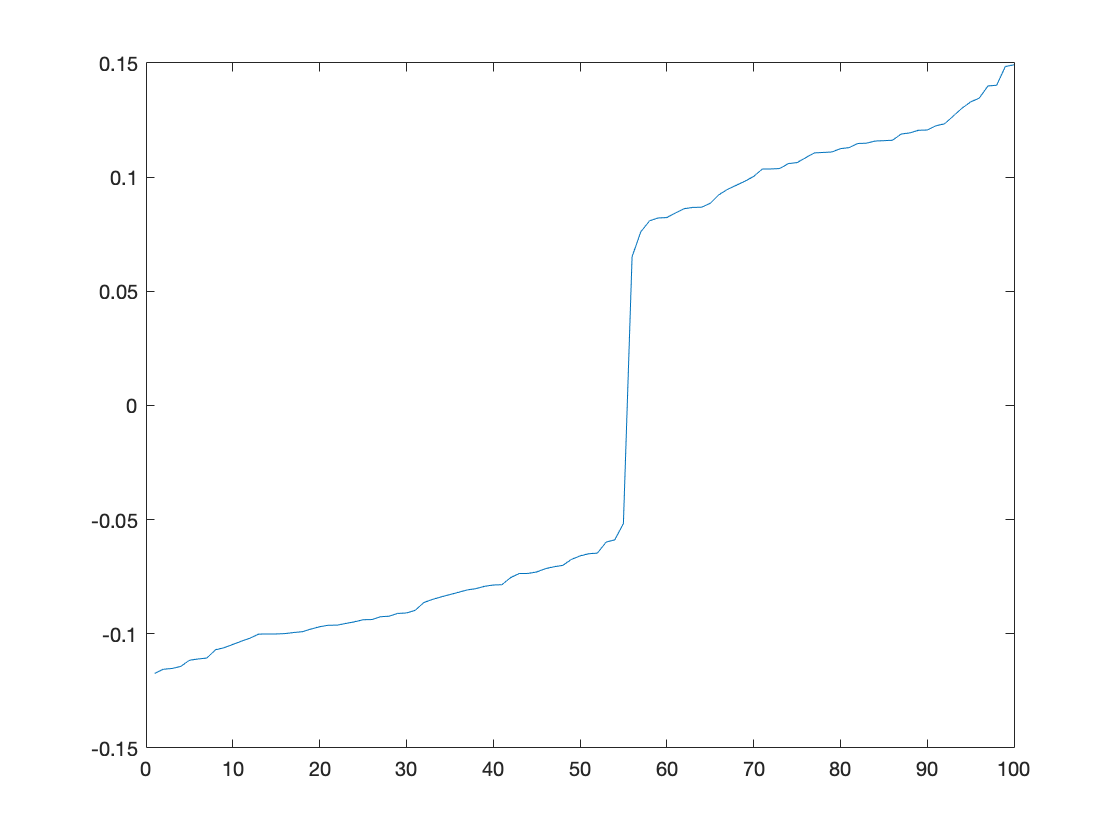

figure('Name','Sorted Fiedler Vector');
plot(sort(fv));